# Data Preparation

clc
clear all
close all
rng(0)

A = [1  1  1  0  0  0  0  0  0;
     0  0  0  1  1  1  0  0  0;
     0  0  0  0  0  0  1  1  1;
    -1  0  0 -1  0  0 -1  0  0;
     0 -1  0  0 -1  0  0 -1  0;
     0  0 -1  0  0 -1  0  0 -1];
pinvA = pinv(A);
m = size(A, 2);
N = null(A, 'rational');
pinvN = pinv(N);

# Load data from random data generator

buffer_train = load('ImitationLearning\TrainingData\Data\train.mat', 'buffer').buffer';
buffer_validation = load('ImitationLearning\TrainingData\Data\validation.mat', 'buffer').buffer';

buffer = [buffer_train, buffer_validation]

buffer = 1.0e+05 *

    4.2228    4.2262    4.2266    4.2207    4.2202    4.2298    4.2226    4.2259    4.2212    4.2286    4.2203    4.2277    4.2237    4.2189    4.2221    4.2286    4.2240    4.2251    4.2282    4.2322    4.2230    4.2277    4.2216    4.2242    4.2238    4.2260    4.2297    4.2270    4.2250    4.2290    4.2218    4.2251    4.2318    4.2226    4.2242    4.2237    4.2286    4.2265    4.2243    4.2284    4.2200    4.2255    4.2265    4.2257    4.2279    4.2240    4.2252    4.2215    4.2197    4.2254
    0.0101    0.0120   -0.0149   -0.0120    0.0077    0.0040    0.0045    0.0109    0.0032    0.0066    0.0117    0.0113    0.0076   -0.0098   -0.0041   -0.0107   -0.0010    0.0070   -0.0109    0.0012    0.0113    0.0082   -0.0099    0.0027   -0.0055   -0.0177    0.0083   -0.0154   -0.0093    0.0121   -0.0030    0.0044   -0.0155   -0.0021   -0.0067    0.0030    0.0075    0.0053    0.0055   -0.0070   -0.0084   -0.0019    0.0117    0.0003    0.0053    0.0038   -0.0030    0.000

Nbuffer_variables = size(buffer, 1)

Nbuffer_variables = 28

Nsamples = size(buffer, 2)

Nsamples = 11000


Ninputs = 22

Ninputs = 22

Noutputs = 5

Noutputs = 5


X = buffer(1:Ninputs, :); size(X)

ans =           22       11000


Y = buffer(Ninputs+1:Ninputs+Noutputs, :); size(Y)

ans =            5       11000


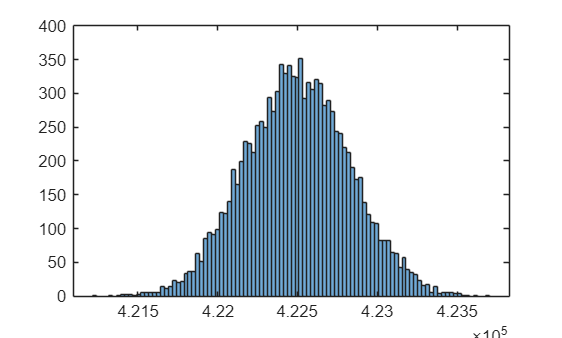


figure
histogram(X(1, :), 100)

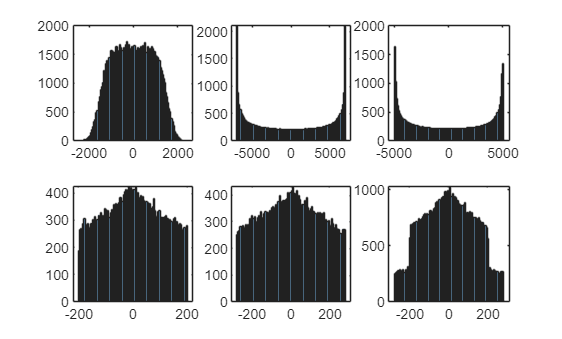


figure
subplot(2, 3, 1)
histogram(X(2:10, :), 100)
subplot(2, 3, 2)
histogram(X(11:13, :), 100)
subplot(2, 3, 3)
histogram(X(14:16, :), 100)
subplot(2, 3, 4)
histogram(X(17:19, :), 100)
subplot(2, 3, 5)
histogram(X(20:22, :), 100)
subplot(2, 3, 6)
histogram(A*pinvA*X(17:22, :), 100)

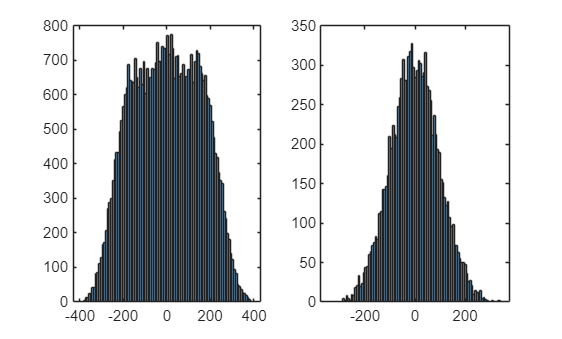


figure
subplot(1, 2, 1)
histogram(Y(1:4, :), 100)
subplot(1, 2, 2)
histogram(Y(5, :), 100)

Absolute maximum L.I. circulating currents (assuming ie_ref_max~ie_max)

ixy = X(17:22, :);
iB = pinvA * ixy;
max(abs(iB(:)))

ans = 159.6243


ie = Y(1:4, :);
ie_max = max(abs(ie(:)))

ie_max = 393.8507

Input/outputs limits

Ax = 7000;
Ay = 5000;
[ix_max, iy_max, is_max, vo_max, vB_max] = max_values(Ax, Ay)

ix_max = 200

iy_max = 280

is_max = 250

vo_max = 1000

vB_max = 12000

Csm = 20e-3;
Nsm = 4;
C = Csm / Nsm

C = 0.0050

vc_mean_ref = vB_max + vo_max

vc_mean_ref = 13000


VCdiff = 0.002;
Emean = C/2 * (vc_mean_ref)^2  *1.1;            % Capacitor mean energy
E = Emean * ((1+2*VCdiff)^2-1) *ones(9, 1);     % Capacitor energy deviation
VX = Ax                        *1.1*ones(3, 1); % Input voltage
VY = Ay                        *1.1*ones(3, 1); % Output voltage
IX = ix_max                    *1.1*ones(3, 1); % Input current
IY = iy_max                    *1.1*ones(3, 1); % Output current

IE = is_max                    *2*ones(4, 1);   % L.I. circulating currents
VO = vo_max;                                    % Common mode voltage

Xmax = [Emean; E; VX; VY; IX; IY]

Xmax = 1.0e+05 *

    4.6475
    0.0373
    0.0373
    0.0373
    0.0373
    0.0373
    0.0373
    0.0373
    0.0373
    0.0373
    0.0770
    0.0770
    0.0770
    0.0550
    0.0550


Ymax = [IE; VO]

Ymax =          500
         500
         500
         500
        1000


# Preprocessing

Input/output sizes (MUST FIT WITH THE BUFFER SIZE)

[Ninputs, Nsamples] = size(X)

Ninputs = 22

Nsamples = 11000

[Noutputs, Nsamples] = size(Y)

Noutputs = 5

Nsamples = 11000

Normalization

X = X ./ Xmax;
Y = Y ./ Ymax;

Training/validation split

% % Randomly shuffle indices
% idx_split = randperm(Nsamples);
% 
% % Define the split
% Nsamples_train = round(0.8 * Nsamples);
% idx_tr = idx_split(1:Nsamples_train);
% idx_val = idx_split(Nsamples_train + 1:end);
% 
% X_tr = X(:, idx_tr);
% Y_tr = Y(:, idx_tr);
% X_val = X(:, idx_val);
% Y_val = Y(:, idx_val);

X_tr  = buffer_train(1:Ninputs, :) ./ Xmax;
Y_tr  = buffer_train(Ninputs+1:Ninputs+Noutputs, :) ./ Ymax;
X_val = buffer_validation(1:Ninputs, :) ./ Xmax;
Y_val = buffer_validation(Ninputs+1:Ninputs+Noutputs, :) ./ Ymax;

Transform to dlarray

dlX     = dlarray(X, 'CB');
dlY     = dlarray(Y, 'CB');
dlX_tr  = dlarray(X_tr, 'CB');
dlY_tr  = dlarray(Y_tr, 'CB');
dlX_val = dlarray(X_val, 'CB');
dlY_val = dlarray(Y_val, 'CB');

# Exploratory data analysis

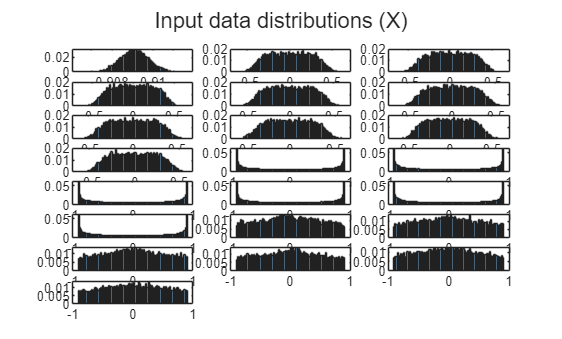

n_cols = 3;

figure
for idx = 1:Ninputs
    subplot(ceil(Ninputs / n_cols), n_cols, idx);
    if or(min(X(idx, :))<-1, max(X(idx, :))>1)
        histogram(X(idx, :), 100, 'Normalization', 'probability', 'FaceColor', 'red', 'EdgeColor', 'red');
    else
        histogram(X(idx, :), 100, 'Normalization', 'probability');
    end
    % title(['X', num2str(idx)]);
    % ylabel('Freq');
end
sgtitle('Input data distributions (X)')

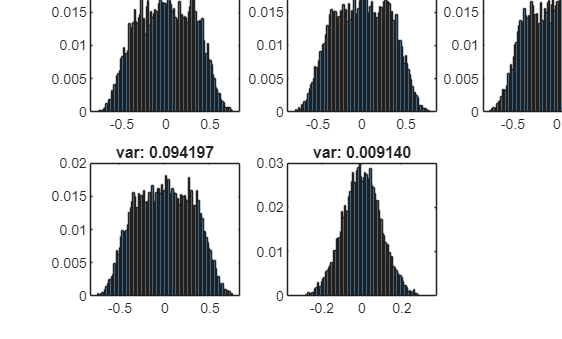


figure
for idx = 1:Noutputs
    subplot(ceil(Noutputs / n_cols), n_cols, idx)
    if or(min(Y(idx, :))<-1, max(Y(idx, :))>1)
        histogram(Y(idx, :), 100, 'Normalization', 'probability', 'FaceColor', 'red', 'EdgeColor', 'red')
    else
        histogram(Y(idx, :), 100, 'Normalization', 'probability')
    end
    title(sprintf('var: %f', var(Y(idx, :))))
end
sgtitle('Output data distributions (Y)')

# Dimensionality reduction for state space visualization

## PCA

Input

% [coeff, score, latent] = pca(X');
% 
% figure
% subplot(1, 2 ,1)
% scatter(score(:, 1), score(:, 2), 10, 'filled', 'MarkerFaceAlpha', 0.1);
% title('2D');
% xlabel('pca_1');
% ylabel('pca_2');
% 
% subplot(1, 2, 2)
% scatter3(score(:, 1), score(:, 2), score(:, 3), 10, 'filled', 'MarkerFaceAlpha', 0.1);
% title('3D');
% xlabel('pca_1');
% ylabel('pca_2');
% zlabel('pca_3');
% 
% sgtitle('PCA X')

Output

% [coeff, score, latent] = pca(Y');
% 
% figure
% subplot(1, 2, 1)
% scatter(score(:, 1), score(:, 2), 10, 'filled', 'MarkerFaceAlpha', 0.1);
% title('2D');
% xlabel('pca_1');
% ylabel('pca_2');
% 
% subplot(1, 2, 2)
% scatter3(score(:, 1), score(:, 2), score(:, 3), 10, 'filled', 'MarkerFaceAlpha', 0.1);
% title('3D');
% xlabel('pca_1');
% ylabel('pca_2');
% zlabel('pca_3');
% 
% sgtitle('PCA Y')

## Clustering

% n_clusters = 5; % Número de clusters
% epsilon = 0.1;  % Radio máximo para DBSCAN
% minPts = 5;     % Mínimo número de puntos para DBSCAN
% 
% % K-means
% [idx_kmeans, C_kmeans] = kmeans(Y', n_clusters, 'Replicates', 10);
% 
% % DBSCAN
% idx_dbscan = dbscan(Y', epsilon, minPts);
% 
% % GMM
% gmm = fitgmdist(Y', n_clusters, 'RegularizationValue', 1e-5);
% idx_gmm = cluster(gmm, Y');
% 
% % PCA
% num_dims = 3;
% [coeff, score, latent] = pca(Y');
% X_reduced = score(:, 1:num_dims);
% 
% figure
% 
% % K-means
% subplot(1, 3, 1)
% scatter3(X_reduced(:, 1), X_reduced(:, 2), X_reduced(:, 3), 10, idx_kmeans, 'filled');
% title('K-means'); xlabel('pca_1'); ylabel('pca_2'); zlabel('pca_3');
% 
% % DBSCAN
% subplot(1, 3, 2)
% scatter3(X_reduced(:, 1), X_reduced(:, 2), X_reduced(:, 3), 10, idx_dbscan, 'filled');
% title('DBSCAN'); xlabel('pca_1'); ylabel('pca_2'); zlabel('pca_3');
% 
% % GMM
% subplot(1, 3, 3)
% scatter3(X_reduced(:, 1), X_reduced(:, 2), X_reduced(:, 3), 10, idx_gmm, 'filled');
% title('GMM'); xlabel('pca_1'); ylabel('pca_2'); zlabel('pca_3');
% 
% sgtitle('Clustering in Original Space');

## UMAP

% pyenv('Version', '3.12', 'ExecutionMode', 'OutOfProcess')
% system('pip install umap-learn')

2D

% code =  [
%           "import umap"
%           "import numpy as np"
%           "reducer = umap.UMAP(n_neighbors=15, min_dist=0.001, n_components=2)"
%           "Xumap = reducer.fit_transform(np.transpose(X))"
%         ];
% 
% code = strjoin(code, newline);
% 
% Xumap = double(pyrun(code, 'Xumap', X=X));
% Yumap = double(pyrun(code, 'Xumap', X=Y));
% 
% figure;
% subplot(1, 2, 1);
% scatter(Xumap(:, 1), Xumap(:, 2), 1, 'filled');
% colormap(jet);
% title('UMAP X');
% xlabel('umap_1'); ylabel('umap_2'); grid on;
% 
% subplot(1, 2, 2);
% scatter(Yumap(:, 1), Yumap(:, 2), 1, 'filled');
% colormap(jet);
% title('UMAP Y');
% xlabel('umap_1'); ylabel('umap_2'); grid on;

3D

% code =  [
%           "import umap"
%           "import numpy as np"
%           "reducer = umap.UMAP(n_neighbors=15, min_dist=0.001, n_components=3)"
%           "Xumap = reducer.fit_transform(np.transpose(X))"
%         ];
% 
% code = strjoin(code, newline);
% 
% Xumap = double(pyrun(code, 'Xumap', X=X));
% Yumap = double(pyrun(code, 'Xumap', X=Y));
% 
% figure;
% subplot(1, 2, 1);
% scatter3(Xumap(:, 1), Xumap(:, 2), Xumap(:, 3), 1, 'filled');
% colormap(jet);
% title('UMAP X');
% xlabel('umap_1'); ylabel('umap_2'); zlabel('umap_3'); grid on;
% 
% subplot(1, 2, 2);
% scatter3(Yumap(:, 1), Yumap(:, 2), Yumap(:, 3), 1, 'filled');
% colormap(jet);
% title('UMAP Y');
% xlabel('umap_1'); ylabel('umap_2'); zlabel('umap_3'); grid on;